currentFolder = pwd;
splitted_str = strsplit(currentFolder,'\');
index = contains(splitted_str,'CableSSB-zh');
if ~any(index)
    error('请进入一个在''CableSSB-zh''内的文件夹')
end
mainpath = '';
for i=1:length(splitted_str)
    if index(i)
        path = join(splitted_str(1:i),'\');
        break
    else
        continue
    end
end
MainPath = genpath(path{1});
addpath(MainPath)

clear all
clc

# 1. 最简单情形：1斜拉索和2吊索的协作体系模型

## 1. 使用buildExample()构造一个协作体系桥梁对象，函数定义见最后

b = CableStayedSuspension_Bridge;
buildExample(b);

Is building a Cable-Stayed Suspension Bridge...


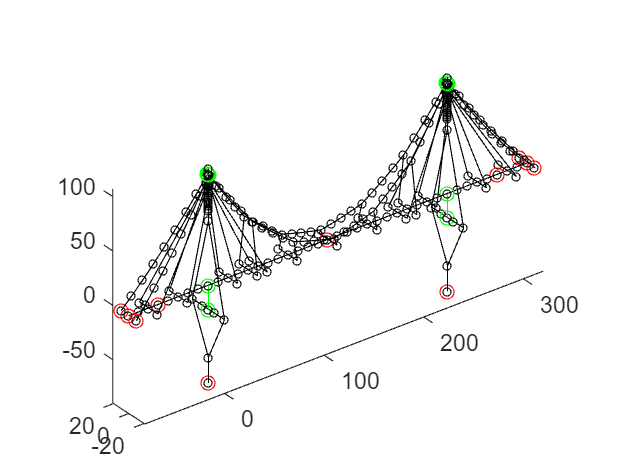

ans =   Figure (1) - 属性:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [440 338 560 420]
       Units: 'pixels'

  显示 所有属性


b.plot

output_method = OutputToAnsys(b,"JobName",'TotalModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge\result.out');
b.OutputMethod = output_method;
b.output

## 2. 无索模型

% 无索模型
bridge_state = NoCable_Bridge(b);
bridge_state.build

Is building a Brigde without Cable System...


output_method = OutputToAnsys(bridge_state,"JobName",'NonCableModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge\result.out');
bridge_state.OutputMethod = output_method;
[FEModel,isEquationCompleted] = bridge_state.getFiniteElementModel;

Is getting Finite Element Model from ANSYS...



% 优化弯曲应变能
bridge_state.optimBendingStrainEnergy('MaxIter',25,'DiffMinChange',1e4);

Is optimizing the Bending Strain Energy...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      14    4.962687e+05    0.000e+00    2.281e-01
    1      28    4.962685e+05    0.000e+00    2.281e-01    4.471e-01
    2      42    4.962675e+05    0.000e+00    2.281e-01    2.235e+00
    3      56    4.962625e+05    0.000e+00    2.281e-01    1.118e+01
    4      70    4.962376e+05    0.000e+00    2.281e-01    5.588e+01
    5      84    4.961129e+05    0.000e+00    2.281e-01    2.794e+02
    6      98    4.954903e+05    0.000e+00    2.278e-01    1.397e+03
    7     112    4.923908e+05    0.000e+00    2.265e-01    6.976e+03
    8     126    4.772313e+05    0.000e+00    2.198e-01    3.469e+04
    9     140    4.095202e+05    0.000e+00    1.873e-01    1.687e+05
   10     154    2.316884e+05    0.000e+00    9.642e-02    7.280e+05
   11     168    2.122536e+05    0.000e+00    8.988e-02    3.357e+05
   1

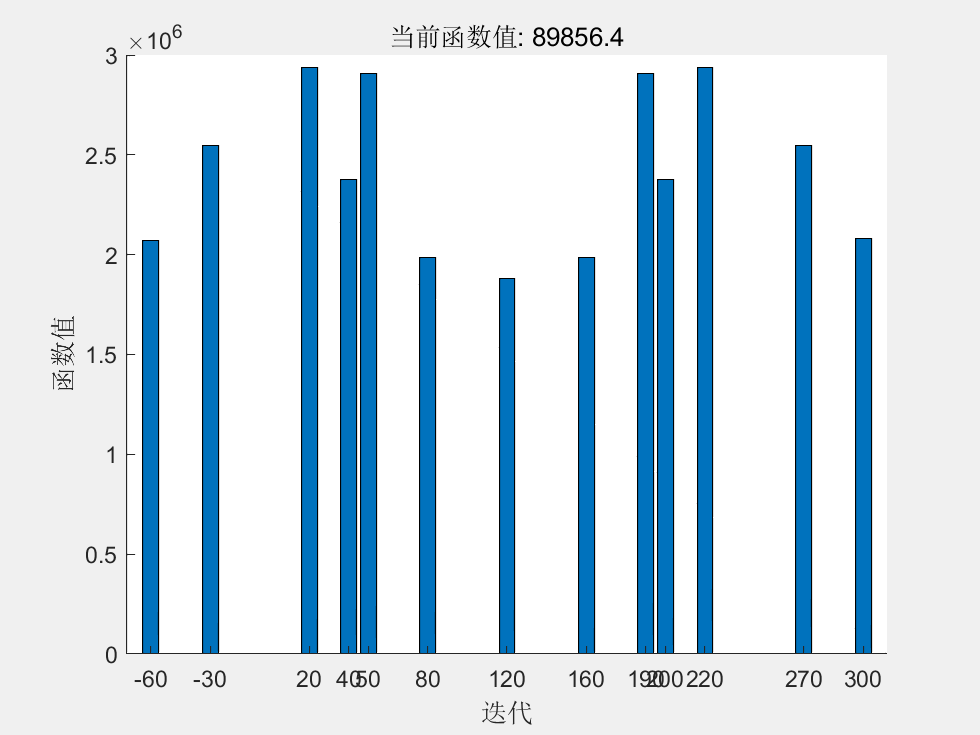


% 结果呈现
Map_Pz = bridge_state.Result_Iteration.Iter_Pz;
max_iter = bridge_state.Iter_Optimization;
Pz_final = Map_Pz(max_iter);
X = bridge_state.OriginalBridge.getSortedGirderPointXCoord([bridge_state.OriginalBridge.findStructureByClass('Hanger'),bridge_state.OriginalBridge.findStructureByClass('StayedCable')]);
bar(X,Pz_final)


% 无索模型的ANSYS结果
output_method = OutputToAnsys(bridge_state,"JobName",'NonCableModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\Optimed_NC_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\Optimed_NC_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\Optimed_NC_Bridge\result.out');
bridge_state.OutputMethod = output_method;
bridge_state.output

## 测试：是否成功建立模型

% 根据最优设计竖向力Pz_final, 计算此时的斜拉索力、吊索力、主缆内力

% 计算吊索力和主缆内力
bridge_state.solveCableShape(Pz_final);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.604655e+03    0.000e+00    4.283e+02
    1      12    7.871990e+01    0.000e+00    1.095e+02    8.171e+00
    2      18    1.653500e+01    0.000e+00    1.934e+01    4.599e+00
    3      24    8.582853e+00    0.000e+00    1.322e+01    4.835e+00
    4      31    2.759236e+00    0.000e+00    1.343e+01    1.952e+00
    5      37    2.461347e+00    0.000e+00    6.295e+00    1.059e+00
    6      43    1.093340e+00    0.000e+00    9.976e+00    1.211e+00
    7      49    2.786233e-01    0.000e+00    3.668e+00    3.760e-01
    8      55    2.047206e-01    0.000e+00    9.420e-01    3.524e-01
    9      61    1.084068e-01    0.000e+00    3.209e+00    4.140e-01
   10      67    1.059348e-02    0.000e+00    4.838e-01    1.703e-01

fmincon 已停止，因为目标函数值 1.059348e-02 小于
options

ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2839 -3.5679 -4.8518 -6.1357 -6.9680 -7.8003 -8.6326 -9.4649 -9.8072 -10.1495 -10.4918 -10.8341 -10.4915 -10.1489 -9.8063 -9.4637 -8.6300 -7.7963 -6.9625 -6.1288 -4.8466 -3.5644 -2.2822 -1]
                   Z: [101.8000 86.3380 71.7421 57.9788 45.0167 36.4955 28.5949 21.2967 14.5843 11.4458 8.8058 6.6584 4.9984 6.6583 8.8058 11.4458 14.5843 21.2967 28.5948 36.4955 45.0167 57.9788 71.7421 86.3380 101.8000]
              Strain: [1.4773e-04 1.4198e-04 1.3654e-04 1.3143e-04 1.0535e-04 1.0221e-04 9.9297e-05 9.6614e-05 8.3918e-05 8.2811e-05 8.1894e-05 8.1165e-05 8.1165e-05 8.1894e-05 8.2811e-05 8.3918e-05 9.6615e-05 9.9298e-05 1.0221e-04 1.0535e-04 … ]
    UnstressedLength: [18.4564 17.7375 17.0592 16.4199 13.1638 12.7710 12.4074 12.0723 10.4866 10.3483 10.2338 10.1427 10.1427 10.2338 10.3483 10.4866 12.0724 12.4076 12.7711 13

resumeSymmetrical called!



% 计算斜拉索索力
X = bridge_state.XCoordOfPz;
for i=1:length(bridge_state.ReplacedStayedCable)
    stayed_cable = bridge_state.ReplacedStayedCable(i);
    Point_Bottom = stayed_cable.findGirderPoint();
    X_Bottom = [Point_Bottom.X];
    P_girder_z = zeros(1,length(X_Bottom));
    for j=1:length(X)
        index = abs(X(j)-X_Bottom) < 1e-5;
        P_girder_z(index) = Pz_final(j);
    end
    stayed_cable.getP(P_girder_z);
end
% 导出协作体系桥梁模型到ANSYS
b.output

# 2. MATLAB与ANSYS联动性测试

## 功能开发

## 测试：是否能够跑通

# 3. MATLAB控制ANSYS进行优化

% 优化的整体思路：以斜拉索和吊索的初应变为设计变量，其存在下限为0，上限为1，目标函数是与设计竖向力的MSE

% 1. 斜拉索和吊索的初应变作为设计变量
%   1.1 列出变量
%   下面是ObjFunc的内容
%   1.2 变量对应应变，应变对应内力，内力对应P_girder_z（注意对称）
%   1.3 根据P_girder_z，主缆找形（注意主缆找形时，嵌套优化算法的初值赋予，以加快速度）
%   1.4 步骤(1.2)得到的斜拉索和吊索的应变对应实常数，步骤(1.3)的主缆的应变对应实常数
%   1.5 ANSYS根据当前实常数，进行求解
%   1.6 ANSYS中提取数据：求解后的斜拉索索力和吊索力、求解后的斜拉索上下端位置，求解后的吊索上下端位置；
%   1.7 根据步骤(1.6)得到的数据，在ANSYS中计算设计竖向力，并导出设计竖向力
%   1.8 MATLAB导入设计竖向力，与理想的设计竖向力求MSE



# 工具函数

function buildExample(obj)
    disp('Is building a Cable-Stayed Suspension Bridge...')
    girder1_sectiondata = UserSection(2,5,40,40,9,2); % 定义截面数据，UserSection是用户自定义截面数据，User(A,Ixx,Iyy,Izz,TKy,TKz) ，单位: m
    girder1_materialdata = MaterialData_Q345; % 定义材料属性，MaterialData_Q345为内置的Q345钢的材料属性，单位: N, m
    Sec_girder1 = Section('主跨主梁Girder',girder1_sectiondata); % 定义截面，后面在定义后面的结构时，使用这里定义的Sec_girder。这里的截面名称'主梁Girder'会出现在Ansys宏文件的注释中，方便检查
    Mat_girder1 = Material('主跨主梁Girder',girder1_materialdata); % 定义材料，后面在定义后面的结构时，使用这里定义的Mat_girder。
    ET_girder1 = Beam188; % 单元类型选择为Ansys中的Beam188单元。

    % 主跨加劲梁
    L = 10+zeros(1,24); % 该段加劲梁的分段情况，只需要输入每一段的正确比例就可以
    CoordA_girder1 = [0,0,0]; % 加劲梁左端点A的位置，"左"代表 X向数值更小的方向。
    CoordB_girder1 = [240,0,0]; % 加劲梁右端点B的位置
    girder1 = obj.buildGirder(CoordA_girder1,CoordB_girder1,L,Sec_girder1,Mat_girder1,ET_girder1); % 根据比例L，对CoordA和CoordB线性插值

    Point_Hanger_girder1 = girder1.findPoint('Interval','X','ascend',[40,40,40,40,40]); % 'ascend'时按X正方向距离PointA的距离，寻找girder1的点。这些点是吊索作用点
    Point_StayedCable_girder1_1 = girder1.findPoint('Interval','X','ascend',[20,30]); % 这些点是靠近PointA的斜拉索作用点
    Point_StayedCable_girder1_2 = girder1.findPoint('Interval','X','descend',[20,30]); % 这些点是靠近PointB的斜拉索作用点
    Point_Hanger_girder1 = Point_Hanger_girder1.sort('X');% 按X正方向的顺序排列
    Point_StayedCable_girder1_1  = Point_StayedCable_girder1_1.sort('X');
    Point_StayedCable_girder1_2 = Point_StayedCable_girder1_2.sort('X');

    % 边跨加劲梁
    girder2_sectiondata = UserSection(3,5,40,40,9,2); % 定义截面数据，UserSection是用户自定义截面数据，User(A,Ixx,Iyy,Izz,TKy,TKz) ，单位: m
    girder2_materialdata = MaterialData_Q345; % 定义材料属性，MaterialData_Q345为内置的Q345钢的材料属性，单位: N, m
    Sec_girder2 = Section('边跨主梁Girder',girder2_sectiondata); % 定义截面，后面在定义后面的结构时，使用这里定义的Sec_girder。这里的截面名称'主梁Girder'会出现在Ansys宏文件的注释中，方便检查
    Mat_girder2 = Material('边跨主梁Girder',girder2_materialdata); % 定义材料，后面在定义后面的结构时，使用这里定义的Mat_girder。
    ET_girder2 = Beam188; % 单元类型选择为Ansys中的Beam188单元。

    % 边跨1加劲梁
    L = 10+zeros(1,8);
    CoordA_girder2 = [-80,0,0];
    CoordB_girder2 = CoordA_girder1;
    girder2 = obj.buildGirder(CoordA_girder2,CoordB_girder2,L,Sec_girder2,Mat_girder2,ET_girder2);
    
    Point_StayedCable_girder2 = girder2.findPoint('Interval','X','descend',[30,30]).sort('X');
    
    % 边跨2加劲梁
    L = 10+zeros(1,8);
    CoordA_girder3 = CoordB_girder1;
    CoordB_girder3 = [320,0,0];
    girder3 = obj.buildGirder(CoordA_girder3,CoordB_girder3,L,Sec_girder2,Mat_girder2,ET_girder2);

    Point_StayedCable_girder3 = girder3.findPoint('Interval','X','ascend',[30,30]).sort('X');
    
    % 将加劲梁和锚碇在交点处融合在一起
    girder = [girder2,girder1,girder3];% 这个对象数组的前后顺序就是X方向的顺序。
    girder.merge;

     %% 桥塔
    % 定义：截面、材料、单元类型
    tower_sectiondata = BoxSection(7,7,1,1,1,1);
    tower_materialdata = MaterialData_C60;
    Sec_tower = Section('桥塔Tower',tower_sectiondata);
    Mat_tower = Material('桥塔Tower',tower_materialdata);
    ET_tower = Beam188;
    
    % 从CAD中导入桥塔的线模型
    model_path_tower = 'Example-Tower.txt';
    Method_Creating = InputFromAutoCAD(model_path_tower);
    
    % 桥塔1
    fun_handle = @(tower) tower.findPoint('Index','Z','ascend',1);% 寻找参考点的方法，输入tower对象，输出参考点
    Coord_MoveTo_tower1 = [0,0,-90];% 塔根位置
    tower1 = obj.buildTowerByInput(Method_Creating,fun_handle,Coord_MoveTo_tower1,Sec_tower,Mat_tower,ET_tower);
    Point_MainCable_tower1 = tower1.findPoint("Index","Z","descend",2).sort('Z'); % 主缆索鞍点,按Z正方向排列
    Point_StayedCable_tower1 = tower1.findPoint("Index","Z","descend",[3,4]).sort('Z'); % 斜拉索锚固位置（还要经过刚臂转化到斜拉索上）
    
    % 桥塔2
    Coord_MoveTo_tower2 = [240,0,-90];
    tower2 = obj.buildTowerByInput(Method_Creating,fun_handle,Coord_MoveTo_tower2,Sec_tower,Mat_tower,ET_tower);
    Point_MainCable_tower2 = tower2.findPoint("Index","Z","descend",2).sort('Z');
    Point_StayedCable_tower2 = tower2.findPoint("Index","Z","descend",[3,4]).sort('Z');
    
    Coord_MoveTo_pier1 = [-50,0,-60];% 辅助墩墩底位置
    Coord_MoveTo_pier2 = [290,0,-60];

    %% 刚臂
    % 定义：截面、材料、单元类型材料
    rigid_beam_sectiondata = RectangleSection(5,5);
    rigid_beam_materialdata = MaterialData_RigidBeam;
    Sec_rigidbeam = Section('刚臂Rigid Beam',rigid_beam_sectiondata);
    Mat_rigidbeam = Material('刚臂Rigid Beam',rigid_beam_materialdata);
    ET_rigidbeam = Beam188;
    
    % girder1 与 Hanger 之间的RigidBeam，均为按X正方向排列
    offset1 = [0,12,0];
    offset2 = [0,-12,0];
    rigidbeam_1 = obj.buildRigidBeamByOffset(Point_Hanger_girder1,girder1,offset1,Sec_rigidbeam,Mat_rigidbeam,ET_rigidbeam);
    rigidbeam_2 = obj.buildRigidBeamByOffset(Point_Hanger_girder1,girder1,offset2,Sec_rigidbeam,Mat_rigidbeam,ET_rigidbeam);
    % girder1 与 StayedCable 之间的RigidBeam
    rigidbeam_3 = obj.buildRigidBeamByOffset(Point_StayedCable_girder1_1,girder1,offset1,Sec_rigidbeam,Mat_rigidbeam,ET_rigidbeam);
    rigidbeam_4 = obj.buildRigidBeamByOffset(Point_StayedCable_girder1_1,girder1,offset2,Sec_rigidbeam,Mat_rigidbeam,ET_rigidbeam);
    rigidbeam_5 = obj.buildRigidBeamByOffset(Point_StayedCable_girder1_2,girder1,offset1,Sec_rigidbeam,Mat_rigidbeam,ET_rigidbeam);
    rigidbeam_6 = obj.buildRigidBeamByOffset(Point_StayedCable_girder1_2,girder1,offset2,Sec_rigidbeam,Mat_rigidbeam,ET_rigidbeam);
    % girder2 与 StayedCable 之间的RigidBeam
    rigidbeam_7 = obj.buildRigidBeamByOffset(Point_StayedCable_girder2,girder2,offset1,Sec_rigidbeam,Mat_rigidbeam,ET_rigidbeam);
    rigidbeam_8 = obj.buildRigidBeamByOffset(Point_StayedCable_girder2,girder2,offset2,Sec_rigidbeam,Mat_rigidbeam,ET_rigidbeam);
    % girder3 与 StayedCable 之间的RigidBeam
    rigidbeam_9 = obj.buildRigidBeamByOffset(Point_StayedCable_girder3,girder3,offset1,Sec_rigidbeam,Mat_rigidbeam,ET_rigidbeam);
    rigidbeam_10 = obj.buildRigidBeamByOffset(Point_StayedCable_girder3,girder3,offset2,Sec_rigidbeam,Mat_rigidbeam,ET_rigidbeam);
    % tower1 与 StayedCable 之间的RigidBeam，均为按Z正方向排列
    offset3 = [0,2,0];
    offset4 = [0,-2,0];
    rigidbeam_11 = obj.buildRigidBeamByOffset(Point_StayedCable_tower1,tower1,offset3,Sec_rigidbeam,Mat_rigidbeam,ET_rigidbeam);
    rigidbeam_12 = obj.buildRigidBeamByOffset(Point_StayedCable_tower1,tower1,offset4,Sec_rigidbeam,Mat_rigidbeam,ET_rigidbeam);
    % tower2 与 StayedCable 之间的RigidBeam
    rigidbeam_13 = obj.buildRigidBeamByOffset(Point_StayedCable_tower2,tower2,offset3,Sec_rigidbeam,Mat_rigidbeam,ET_rigidbeam);
    rigidbeam_14 = obj.buildRigidBeamByOffset(Point_StayedCable_tower2,tower2,offset4,Sec_rigidbeam,Mat_rigidbeam,ET_rigidbeam);

    %% StayedCable
    stayedcable_sectiondata = CircleSection(0.12);
    stayedcable_materialdata = MaterialData_Cable;
    Sec_stayedcable = Section('斜拉索Stayed',stayedcable_sectiondata);
    Mat_stayedcable = Material('斜拉索Stayeed',stayedcable_materialdata);
    ET_stayedcable = Link10;
    
    % girder1 与 tower1 之间的 StayedCable
    stayedcable_1 = obj.buildStayedCable(rigidbeam_3.ConnectPoint,rigidbeam_11.ConnectPoint,rigidbeam_3,rigidbeam_11,Sec_stayedcable,Mat_stayedcable,ET_stayedcable);
    stayedcable_2 = obj.buildStayedCable(rigidbeam_4.ConnectPoint,rigidbeam_12.ConnectPoint,rigidbeam_4,rigidbeam_12,Sec_stayedcable,Mat_stayedcable,ET_stayedcable);
    % girder1 与 tower2 之间的 StayedCable
    stayedcable_3 = obj.buildStayedCable(rigidbeam_5.ConnectPoint,rigidbeam_13.ConnectPoint.reverse,rigidbeam_5,rigidbeam_13,Sec_stayedcable,Mat_stayedcable,ET_stayedcable);
    stayedcable_4 = obj.buildStayedCable(rigidbeam_6.ConnectPoint,rigidbeam_14.ConnectPoint.reverse,rigidbeam_6,rigidbeam_14,Sec_stayedcable,Mat_stayedcable,ET_stayedcable);
    % girder2 与 tower1 之间的 StayedCable
    stayedcable_5 = obj.buildStayedCable(rigidbeam_7.ConnectPoint,rigidbeam_11.ConnectPoint.reverse,rigidbeam_7,rigidbeam_11,Sec_stayedcable,Mat_stayedcable,ET_stayedcable);
    stayedcable_6 = obj.buildStayedCable(rigidbeam_8.ConnectPoint,rigidbeam_12.ConnectPoint.reverse,rigidbeam_8,rigidbeam_12,Sec_stayedcable,Mat_stayedcable,ET_stayedcable);
    % girder3 与 tower2 之间的 StayedCable
    stayedcable_7 = obj.buildStayedCable(rigidbeam_9.ConnectPoint,rigidbeam_13.ConnectPoint,rigidbeam_9,rigidbeam_13,Sec_stayedcable,Mat_stayedcable,ET_stayedcable);
    stayedcable_8 = obj.buildStayedCable(rigidbeam_10.ConnectPoint,rigidbeam_14.ConnectPoint,rigidbeam_10,rigidbeam_14,Sec_stayedcable,Mat_stayedcable,ET_stayedcable);
    
    %% Cable
    % 定义：截面、材料、单元类型材料
    main_cable_sectiondata = CircleSection(0.36); % 直径0.36m的圆截面
    main_cable_materialdata = MaterialData_Cable; % 使用内置的 MaterialData_Cable的材料数据
    Sec_cable = Section('主缆Cable',main_cable_sectiondata);
    Mat_cable = Material('主缆Cable',main_cable_materialdata);
    ET_cable = Link10;
    
    % 主跨主缆
    CoordA_cable1 = Point_MainCable_tower1.Coord + [0,1,0]; % 左端点坐标
    CoordB_cable1 = Point_MainCable_tower2.Coord + [0,1,0]; % 右端点坐标
    L = 10+zeros(1,24); % 主缆X向分段，长度n=92
    index_hanger = logical([zeros(1,3),1,zeros(1,3),1,zeros(1,3),1,zeros(1,3),1,zeros(1,3),1,zeros(1,3)]);% 吊杆会在主缆哪些位置悬吊，长度n-1=91，X正方向排列，与Cable.ForcePoint方向相同
    
    weight = obj.getGirderWeight;
    count_hanger = sum(index_hanger);
    P_z = -weight/count_hanger/4; % 主跨加劲梁girder1的总重被主跨的StayedCable平分
    P_h_z = P_z+zeros(1,count_hanger); % 初始吊杆力（吊杆和斜拉索竖向力平分加劲梁自重）zhengfangxiang
    P_h_y = -P_h_z*abs((CoordA_cable1(2)-offset1(2))/(CoordA_cable1(3)-offset1(3)));
    P_h_x = zeros(size(P_h_z));
    
    Z_Om = 5; % 主缆跨中点Z
    obj.Params.P_girder_z_MainSpan = P_h_z;
    
    [cable1,Output_MS] = obj.buildMainSpanCable(CoordA_cable1,CoordB_cable1,L,index_hanger,P_h_x,P_h_y,P_h_z,Z_Om,Sec_cable,Mat_cable,ET_cable);
    cable2 = obj.symmetrizeCable(cable1); 
    
    
    % 边跨1主缆
    CoordA_cable2 = [-80,10,0];
    CoordB_cable2 = CoordA_cable1;
    L = 10+zeros(1,8);
    index_hanger = false(1,7);
    P_h_x = [];
    P_h_y = [];
    P_h_z = [];
    F_x = Output_MS.F_x;
    
    cable3 = obj.buildSideSpanCable(CoordA_cable2,CoordB_cable2,L,index_hanger,P_h_x,P_h_y,P_h_z,F_x,Sec_cable,Mat_cable,ET_cable);
    cable4 = obj.symmetrizeCable(cable3);
    
    % 边跨2主缆
    CoordA_cable3 = CoordB_cable1;
    CoordB_cable3 = [320,10,0];
    L = 10+zeros(1,8);
    index_hanger = false(1,7);
    P_h_x = [];
    P_h_y = [];
    P_h_z = [];
    F_x = Output_MS.F_x;
    
    cable5 = obj.buildSideSpanCable(CoordA_cable3,CoordB_cable3,L,index_hanger,P_h_x,P_h_y,P_h_z,F_x,Sec_cable,Mat_cable,ET_cable);
    cable6 = obj.symmetrizeCable(cable5);
    
    cable_PositiveY = [cable3,cable1,cable5];
    cable_NegativeY = [cable4,cable2,cable6];
    cable_PositiveY.merge;
    cable_NegativeY.merge;

    %% Hanger
    % 定义：截面、材料、单元类型材料
    hanger_sectiondata = CircleSection(0.1);
    hanger_materialdata = MaterialData_Q345;
    Sec_hanger = Section('吊杆Hanger',hanger_sectiondata);
    Mat_hanger = Material('吊杆Hanger',hanger_materialdata);
    ET_hanger = Link10;
    
    hanger_1 = obj.buildHanger(rigidbeam_1.ConnectPoint,cable1.ConnectPoint,rigidbeam_1,cable1,Sec_hanger,Mat_hanger,ET_hanger);
    hanger_2 = obj.buildHanger(rigidbeam_2.ConnectPoint,cable2.ConnectPoint,rigidbeam_2,cable2,Sec_hanger,Mat_hanger,ET_hanger);
    
    %% 赋予斜拉索和吊杆初始力
    stayedcable_list = obj.findStructureByClass('StayedCable');
    hanger_list = obj.findStructureByClass('Hanger');
    hanger_stayedcable_list = [stayedcable_list,hanger_list];
    obj.setForceTo(hanger_stayedcable_list,P_z+zeros(1,length(hanger_stayedcable_list)))
    
    %% 耦合 Coupling
    tower1_masterpoint = tower1.Point.findPointByRange([],0,-22.15);
    tower2_masterpoint = tower2.Point.findPointByRange([],0,-22.15);
    CP_tower1_girder = obj.addCoupling(tower1_masterpoint,girder1.PointA,{'Uy','Uz','Rotx'},'Name','塔梁耦合1');
    CP_tower2_girder = obj.addCoupling(tower2_masterpoint,girder1.PointB,{'Uy','Uz','Rotx'},'Name','塔梁耦合2');

    CP_tower1_cable = obj.addCoupling(Point_MainCable_tower1,[cable1.PointA,cable2.PointA],{'Ux','Uy','Uz'},'Name','主缆、塔耦合1');
    CP_tower2_cable = obj.addCoupling(Point_MainCable_tower2,[cable1.PointB,cable2.PointB],{'Ux','Uy','Uz'},'Name','主缆、梁耦合2');
        % 二期恒载
    % FullSpanLoad_girder1_line = girder1.findLineByCenterCoord('X','ascend');
    % FullSpanLoad_girder2_line = girder2.findLineByCenterCoord('X','ascend');
    % FullSpanLoad_girder3_line = girder3.findLineByCenterCoord('X','ascend');
    % FullSpanLoad_girder_line = [FullSpanLoad_girder1_line,FullSpanLoad_girder2_line,FullSpanLoad_girder3_line];
    % FullSpanLoad = UniformLoad(FullSpanLoad_girder_line,'Z',-1900000);
    % obj.addLoad(FullSpanLoad,'Name','二期恒载');   

    %% 约束 Constraint
    
    % 塔底约束
    all_DoF = DoF.All.Name; % {'Ux','Uy','Uz','Rotx','Roty','Rotz'}
    constraint1 = obj.addConstraint(tower1.PointBottom,all_DoF,zeros(1,length(all_DoF)),'Name','塔底固结1');
    constraint2 = obj.addConstraint(tower2.PointBottom,all_DoF,zeros(1,length(all_DoF)),'Name','塔底固结2');
    
    % 梁端约束
    support_DoF_1 = {'Uy','Uz','Rotx'};
    support_DoF_2 = {'Uy','Uz','Rotx'};
    constraint3 = obj.addConstraint(girder2.PointA,support_DoF_1,zeros(1,length(support_DoF_1)),'Name','梁端约束1');
    constraint4 = obj.addConstraint(girder3.PointB,support_DoF_2,zeros(1,length(support_DoF_2)),'Name','梁端约束2');

    % 辅助墩处加劲梁约束
    girder2_PierPoint = girder2.Point.findPointByRange(Coord_MoveTo_pier1(1),[],[]);
    girder3_PierPoint = girder3.Point.findPointByRange(Coord_MoveTo_pier2(1),[],[]);
    constraint5 = obj.addConstraint(girder2_PierPoint,support_DoF_2,zeros(1,length(support_DoF_2)),'Name','辅助墩处加劲梁约束1');
    constraint6 = obj.addConstraint(girder3_PierPoint,support_DoF_2,zeros(1,length(support_DoF_2)),'Name','辅助墩处加劲梁约束2');

    % 主缆地锚固结
    support_DoF_5 = {'Ux','Uy','Uz'};
    support_DoF_6 = {'Ux','Uy','Uz'};
    support_DoF_7 = {'Ux','Uy','Uz'};
    support_DoF_8 = {'Ux','Uy','Uz'};
    constraint7 = obj.addConstraint(cable3.PointA,support_DoF_5,zeros(1,length(support_DoF_5)),'Name','地锚固结1');
    constraint8 = obj.addConstraint(cable4.PointA,support_DoF_6,zeros(1,length(support_DoF_6)),'Name','地锚固结2');
    constraint9 = obj.addConstraint(cable5.PointB,support_DoF_7,zeros(1,length(support_DoF_7)),'Name','地锚固结3');
    constraint10 = obj.addConstraint(cable6.PointB,support_DoF_8,zeros(1,length(support_DoF_8)),'Name','地锚固结4');
    
    % 跨中X向约束
    support_DoF_3 = {'Ux'};
    point_center = girder1.PointCenter; % 跨中点
    constraint11 = obj.addConstraint(point_center,support_DoF_3,zeros(1,length(support_DoF_3)),'Name','跨中点X向固定');
    
end